# Programmierblatt 2

#### Finite Differenzen, Laplace und Poisson Gleichung

Bearbeitende Studierende:

Jonathan Schnitzler    Matr. - Nr: 3465192

Matthias Gültig           Matr. - Nr: 3469020

Anmerkungen: Alle Aufgaben wurden bereits mit der freiwilligen aber sinnvollen Forderung nach Erweiterung bzw. Generalisierbarkeit implementiert

##  Aufgabe 1 (FD-Gitter)

In dieser Aufgabe wird das Gitter $\Omega =\left({\left(0,3\right)}^2 \backslash \left(\left\lbrack 2,3\right)\times \left(0,1\rbrack \right.\right)\right)\backslash \left(\left(0,1\right\rbrack \times \;\left\lbrack 2,3\right)\right)$

Die Grundlegende Idee ist die kleinstmögliche Basis $\Omega {\;}_R$ zu schaffen, sodass $\bar{\Omega {\;}_h \;} \subset \;\Omega {\;}_R$ und ein rechteckiges Würfelgitter ist. Dann reicht es aus diesem allgemeinen Gitter kleinere Rechtecke "auszuschneiden", und man kann jedes beliebige gewünschte Gebiet erhalten.

omeg.o = [0,0]

omeg = struct with fields:
    o: [0 0]
    x: 2
    y: 2
    h: 0.5000


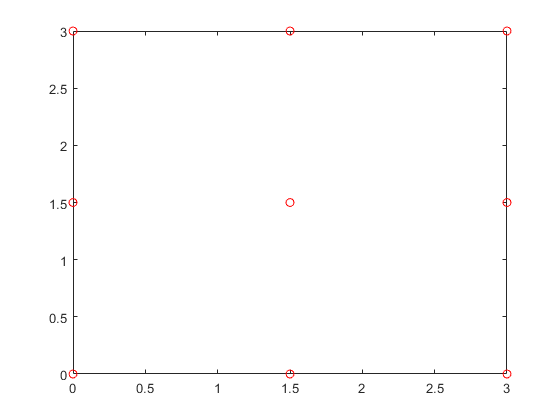

omeg.x = 3;
omeg.y = 3;
omeg.h = 1.5;

Omega = genRectMesh2D(omeg);
Omega = Omega.pointMat;
plot(Omega(:,1), Omega(:,2),'ro');

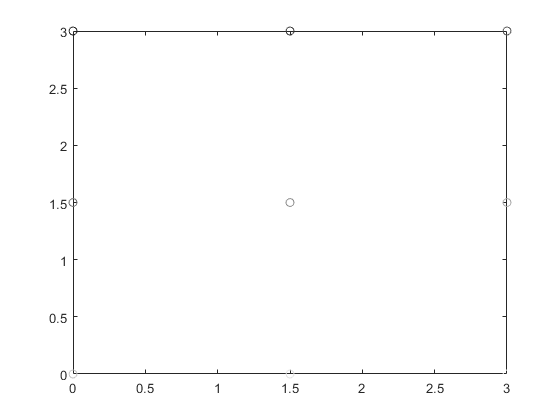




figure;
plot(omeg.o(1),omeg.o(2),'ro');
axis = [omeg.o(1),omeg.o(1)+omeg.x, omeg.o(2), omeg.o(2)+omeg.y];
hold on
nOmega = size(Omega,1);
for k=1:nOmega
    color = ones(3,1)*(k/nOmega);
    plot(Omega(k,1),Omega(k,2),'Color',color,"Marker",'o')
    
    drawnow
    pause(0.025)
end
hold off

%Testing some shit
omeg.o = [0,0];
omeg.x = 3;
omeg.y = 3;
omeg.h = 0.5;
O1 = genRectMesh2D(omeg);
omeg.x = 2;
omeg.y = 2;
omeg.o = [1, 1.5];
O2 = genRectMesh2D(omeg);

O = meshSubtract(O1,O2)

innerPoints = struct with fields:
    x: 1


bP =     1.0000    3.5000


Operands to the logical and (&&) and or (||) operators must be convertible to logical scalar values.

Error in prog2>meshSubtract (line 104)
    if idx > 2 && idx < size(pM,1) 

O = O.pointMat;
plot(O(:,1), O(:,2),'ro');

function OmegaHBar = genRectMesh2D(omeg)
%Input is a struct specifying the origin the X-Length, the Y-Length and the
%Meshsize h
    if mod(omeg.x,omeg.h) ~= 0 || mod(omeg.y,omeg.h) ~= 0
        error("X-Length or Y-Length are not applicable with the Meshsize of h");
    end
    
    nX = omeg.x/omeg.h;
    nY = omeg.y/omeg.h;
    N = (nX+1).*(nY+1);
    OmegaHBar = omeg;
    OmegaHBar.pointMat = zeros(N,2);
    for kY = 0:nY
        for kX = 0:nX
            OmegaHBar.pointMat(kY*(nX+1) + (kX + 1),:) = [omeg.o(1) + kX *omeg.h, omeg.o(2) + omeg.y - kY * omeg.h];
        end
    end
end

function OmegaHBar = meshSubtract(Omega, subOmega)
%Subtracts a rectangular mesh from an arbitrary cubic Mesh while keeping the
%edges
if subOmega.h ~= Omega.h
    error("Meshsizes h are different");
end
h = subOmega.h;

if mod(subOmega.o(1)-Omega.o(1), h) ~= 0 || mod(subOmega.o(2)-Omega.o(2), h) ~= 0
    error("Origins are not a multiple of h appart from each other")
end

%Subtracting inner rectangle without the border
innerPoints.x = subOmega.x - 2*h
innerPoints.y = subOmega.y - 2*h;
innerPoints.o = subOmega.o + [h, h];
innerPoints.h = h;


innerPoints = genRectMesh2D(innerPoints);
Omega.pointMat = meshSubtractWithEdge(Omega.pointMat,innerPoints.pointMat);
border = meshSubtractWithEdge(subOmega.pointMat, innerPoints.pointMat);
pM = Omega.pointMat;


%For every Element on the border check, if it is isolated or not - if remove
for k = 1:2
idx = zeros(size(border,1));
keep = true(size(pM,1),1);
for k1 = 1:size(border,1)
    bP = border(k1,:)
    %Search index of borderPoint bP in pM 
    %and if there is a 
    neighX = false; %neighbour
    neighY = false;
    for k2 = 1:size(pM)
        if equalEps(bP, pM(k2,:))
            idx(k1) = k2;
        elseif equalEps(bP + [0 h],pM(k2,:))
            neighY = true;
        elseif equalEps(bP + [0 -h], pM(k2,:))
            neighY = true;
        end
    end
    if idx > 2 && idx < size(pM,1) 
    
        if equalEps((bP + [-h 0]), pM(idx-1,:)) || equalEps((bP + [h 0]), pM(idx+1,:)) %lexikografisch
            neighX = true;
        end
        
        if ~neighX || ~neighY
        keep(idx(k1)) = false;
        end
    end
end
pM = pM(keep);
end

OmegaHBar = Omega;


end

function Omega = meshSubtractWithEdge(pM, pMSub)
%Input is the point Matrix of a area and an area you want to subtract it
%from - output is the point Matrix of pM without pMSub
%Could be implemented faster
isIn = zeros(size(pM,1),1);
for k1 = 1:size(pM,1)
    for k2 = 1:size(pMSub,1)
        if equalEps(pM(k1,:),pMSub(k2,:))
            isIn(k1) = 1;
            break;
        end
    end
end
Omega = pM(~logical(isIn),:);
end


function equalEps = equalEps(x, y)
    if norm(x-y) < 1e4*eps(min(norm(x),norm(y)))
        equalEps = true;
    else
        equalEps = false;
    end
end
        
% function findNeighbor